# 2D-Fourier Transform

In this section we will implement the 2D Fourier Transform on images and learn about some of its properties.

1. 1 the 2D FFT 

The equations for the FFT and iFFT for an image I of size $M\times N$ are as follows:


$$F\left\lbrace I\left(m,n\right)\right\rbrace \left(u,v\right)=\;\sum_{m=0}^{M-1} \sum_{n=0}^{N-1} I\left(m,n\right)\cdot e^{-2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


and the inverse transform:


$$I\left(m,n\right)=\frac{1}{M\cdot N}\sum_{u=0}^{M-1} \sum_{v=0}^{N-1} F\left(u,v\right)\cdot e^{2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


accounting to MATLAB's indexing, we will rewrite the array indices as such: 


$$F\left(u+1,v+1\right)=\;\sum_{m=0}^{M-1} \sum_{n=0}^{N-1} I\left(m+1,n+1\right)\cdot e^{-2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$



$$I\left(m+1,n+1\right)=\frac{1}{M\cdot N}\sum_{u=0}^{M-1} \sum_{v=0}^{N-1} F\left(u+1,v+1\right)\cdot e^{2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


as for the algorithm, we will implement it by slightly rearranging the equation:


$$F\left(u+1,v+1\right)=\;\sum_{m=0}^{M-1} \left(\sum_{n=0}^{N-1} I\left(m+1,n+1\right)\cdot e^{-2\pi i\left(\frac{v\cdot n}{N}\right)} \right)e^{-2\pi i\left(\frac{u\cdot m}{M}\right)}$$


% __________________________________________________
%|                                                  |
%|                                                  |
%|            1.1 2D-Fourier Transform              |
%|                                                  |
%|__________________________________________________|

% part 3

let's read the beatles.png image, convert it to grayscale, and normalize to $\in \left\lbrack 0,1\right\rbrack$

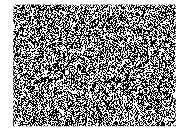

I = imread_normalized("beatles.png");

% 4
my_FFT = dip_fft2(I);
imshow(real(my_FFT))

title('our fft')


let's just check how our algorithm compares to MATLAB's implementation:

imshow(real(F))

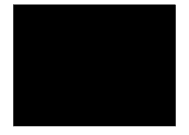

title('MATLAB fft')

imshow(F-my_FFT);

title('the difference between our implementation and MATLAB built in')


### Reconstruct the original image

 by using your inverse-FFT function. Is it identical to the original image? Note that the output of the iFFT are complex numbers - you should display only the real part of the image using imshow(real(-))

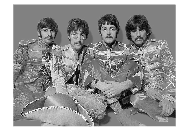

reconstructed_img = dip_ifft2(my_FFT);
imshow(reconstructed_img)

title('reconstructed image')


but are they identical? to answer that we will compute the error, to estimate the loss to the original image by applying $F^{-1} \left\lbrace F\left\lbrace I\left(m,n\right)\right\rbrace \right\rbrace$ 

mse = mean(mean((reconstructed_img - I) .^ 2))

mse = 2.5708e-28 - 5.5161e-29i

# 1.2 Transformation properties

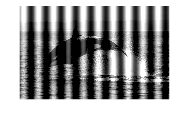

load("freewilly.mat");
imshow(freewilly)

### b. find the frequency of the bars

first, we plotted the first row, which seems to contain the least of the original image information.

row1 = freewilly(1,:)

row1 =     0.5922    0.6412    0.6897    0.7373    0.7835    0.8279    0.8699    0.9094    0.9457    0.9787    1.0079    1.0331    1.0541    1.0706    1.0825    1.0897    1.0922    1.0937    1.0865    1.0785    1.0619    1.0370    1.0118    0.9787    0.9457    0.9094    0.8699    0.8279    0.7835    0.7412    0.6936    0.6451    0.5961    0.5471    0.4985    0.4509    0.4047    0.3604    0.3183    0.2789    0.2425    0.2096    0.1803    0.1551    0.1341    0.1176    0.1057    0.0985    0.1000    0.1024


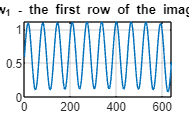

plot(row1);
F = fft(row1);
title('w_1 - the first row of the image')
grid on

by plotting it, it seems clear that $B\propto\sin \left(\frac{2\pi f_x }{N}\;x\right)$ and that we can already estimate $f_x$ by counting peaks. 

however, for more accurate and scientific assesment, we chose to go further and calculate it's fourier transform

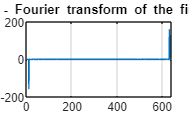


plot(imag(F));
title('im(F\{w_1\}) - Fourier transform of the first row (imaginary part)')
grid on

by plotting the imaginary part we can use the descrete transform identity $\mathcal{F}\left\lbrace \sin \left(\frac{2\pi f_x }{N}\;x\right)\right\rbrace \propto\;i\delta \left(N-f_x \right)-i\delta \left(f_x \right)$ . so we can find $f_x$ by taking the $\underset{k\in \left\lbrack 0,639\right\rbrack }{\mathrm{argmax}} \left(\mathcal{F}\left\lbrace \sin \left(\frac{2\pi f_x }{N}\;x\right)\right\rbrace \left(k\right)\right)$

of course, let's not forget to add one, to account for MATLAB's indexing.

 [argvalue, argmin] = min(imag(F))

argvalue = -160.4060

argmin = 11

 [argvalue, argmax] = max(imag(F))

argvalue = 160.4060

argmax = 631

we get that $f_x =10$ and so the sinusoidal bars follow the equation of $\sin \left(\frac{2\pi }{N}\cdot 10x\right)$. it makes a lot of sense that this is a good estimation, because there are roughly 10 bars in total of N pixels.

### c. create the image of the prison bars and display it

[M, N] = size(freewilly)

M = 400

N = 640

bars = 0.5*sin(2*(pi/N)*10*(1:N))

bars =     0.0490    0.0975    0.1451    0.1913    0.2357    0.2778    0.3172    0.3536    0.3865    0.4157    0.4410    0.4619    0.4785    0.4904    0.4976    0.5000    0.4976    0.4904    0.4785    0.4619    0.4410    0.4157    0.3865    0.3536    0.3172    0.2778    0.2357    0.1913    0.1451    0.0975    0.0490    0.0000   -0.0490   -0.0975   -0.1451   -0.1913   -0.2357   -0.2778   -0.3172   -0.3536   -0.3865   -0.4157   -0.4410   -0.4619   -0.4785   -0.4904   -0.4976   -0.5000   -0.4976   -0.4904


bars = repmat(bars,M,1)

bars =     0.0490    0.0975    0.1451    0.1913    0.2357    0.2778    0.3172    0.3536    0.3865    0.4157    0.4410    0.4619    0.4785    0.4904    0.4976    0.5000    0.4976    0.4904    0.4785    0.4619    0.4410    0.4157    0.3865    0.3536    0.3172    0.2778    0.2357    0.1913    0.1451    0.0975    0.0490    0.0000   -0.0490   -0.0975   -0.1451   -0.1913   -0.2357   -0.2778   -0.3172   -0.3536   -0.3865   -0.4157   -0.4410   -0.4619   -0.4785   -0.4904   -0.4976   -0.5000   -0.4976   -0.4904
    0.0490    0.0975    0.1451    0.1913    0.2357    0.2778    0.3172    0.3536    0.3865    0.4157    0.4410    0.4619    0.4785    0.4904    0.4976    0.5000    0.4976    0.4904    0.4785    0.4619    0.4410    0.4157    0.3865    0.3536    0.3172    0.2778    0.2357    0.1913    0.1451    0.0975    0.0490    0.0000   -0.0490   -0.0975   -0.1451   -0.1913   -0.2357   -0.2778   -0.3172   -0.3536   -0.3865   -0.4157   -0.4410   -0.4619   -0.4785   -0.4904   -0.4976   -0.5000   -0.4976  

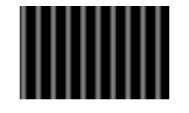

imshow(bars)

### d.Compute the 2D-FFT of the prison bars image, and display its amplitude

bars_fft = fft2(bars)

bars_fft = 1.0e+04 *

   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.6273 - 6.3692i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.000

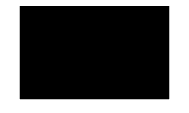

imshow(bars_fft)

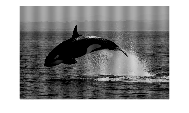

willy_fft = fft2(freewilly);
willy_fft = willy_fft - 1.08*bars_fft;
willy_free = ifft2(willy_fft);
imshow(willy_free)

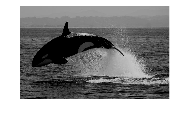

willy_fft = fft2(freewilly);
willy_fft(abs(bars_fft)>1) = 0;
willy_free = ifft2(willy_fft);
imshow(willy_free)

# 2. Scaling, translation and seperability

(a) we Initialized a 128×128 all-zeros matrix. At the center of it, we placed a 40×40 all-ones square, and displayed the image and its 2D-FFT:

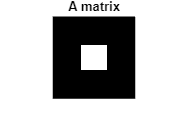

A = zeros(128,128);

A(45:84,45:84) = 1;

figure;
imshow(A);
title('A matrix');

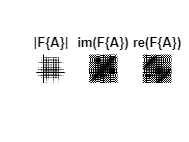


FA = fft2(A);
figure;
subplot(1, 3, 1);
imshow(abs(FA));
title('|F\{A\}|')

subplot(1, 3, 2);
imshow(imag(FA));
title('im(F\{A\})')
subplot(1, 3, 3);
imshow(real(FA));
title('re(F\{A\})')

(b) now we put the square at the bottom right,

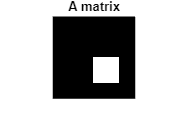

A = zeros(128,128);

A(64:103,64:103) = 1;

figure;
imshow(A);
title('A matrix');

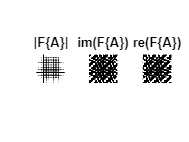


FA = fft2(A);
figure;
subplot(1, 3, 1);
imshow(abs(FA));
title('|F\{A\}|')

subplot(1, 3, 2);
imshow(imag(FA));
title('im(F\{A\})')
subplot(1, 3, 3);
imshow(real(FA));
title('re(F\{A\})')